%% Preparación del entorno
clear;
clc;
close all;

%% Definición simbólica del sistema
syms p53 Stat3 Np63 DNp63
assume(DNp63 >= 0)

% Parámetros
Pp53 = 1.1380;
N = 0.6184;
k = 1.8558;
B = 1.6019;
ANp63p53 = 1.3864;
C1 = 0.8905;
dNp63p53 = 1.0944;
Dp53 = 0.1597;
ANp63s = 0.0053;
Ap53s = 1.1090;
Dstat3 = 0.8895;
Pstat3 = 0.9819;
PNp63 = 5.7201;
Astat3Np = 0.9350;
C2 = 1.2659;
dp53NP = 0.0000;
C3 = 2.8150;
dNp63Np63 = 0.2113;
%DNp63 = 3.3663;

% Ecuaciones del sistema
f1 = (Pp53 + B*(p53^N)/(k^N + p53^N) + ANp63p53*Np63) * C1/(1 + dNp63p53*Np63) - Dp53*p53;
f2 = (Pstat3 + ANp63s*Np63 + Ap53s*p53) - Dstat3*Stat3;
f3 = (PNp63 + Astat3Np*Stat3) * C2/(1 + dp53NP*p53) * C3/(1 + dNp63Np63*Np63) - DNp63*Np63;

bifurcacion = []; % Para almacenar [DNp63, p53, Stat3, Np63, estabilidad]

% Variables simbólicas a resolver
vars = [p53, Stat3, Np63];

% Preparar vector de valores para DNp63
DNp63_vals = linspace(0, 50, 200);
resultados = [];

for i = 1:length(DNp63_vals)
    valor_P = DNp63_vals(i);
    soluciones = vpasolve([subs(f1, DNp63, valor_P)==0, ...
                           subs(f2, DNp63, valor_P)==0, ...
                           subs(f3, DNp63, valor_P)==0], ...
                          [p53, Stat3, Np63]);
    
    % Convertir soluciones a vectores numéricos (puede haber varias)
    p53_sol = double(soluciones.p53);
    Stat3_sol = double(soluciones.Stat3);
    Np63_sol = double(soluciones.Np63);
    
    for j = 1:length(p53_sol)
        x1 = p53_sol(j);
        x2 = Stat3_sol(j);
        x3 = Np63_sol(j);

        % Verificar si el punto es real y no negativo
        if all(isreal([x1 x2 x3])) && all([x1 x2 x3] >= 0)
            % Construir la matriz Jacobiana en el punto
            J = jacobian([f1, f2, f3], [p53, Stat3, Np63]);
            J_num = double(subs(J, [p53, Stat3, Np63, DNp63], [x1, x2, x3, valor_P]));
            autovalores = eig(J_num);
            
            % Clasificación básica de estabilidad
            if all(real(autovalores) < 0)
                tipo = "Estable";
            elseif any(real(autovalores) > 0) && any(real(autovalores) < 0)
                tipo = "Silla";
            else
                tipo = "Inestable";
            end
            
            % Guardar resultado
            resultados = [resultados; {valor_P, x1, x2, x3, tipo}];
        end
    end
end

resultados

resultados = 199×5 cell array
    {[0.2513]}    {[7.2281]}    {[10.2932]}    {[29.8133]}    {["Estable"]}
    {[0.5025]}    {[7.3003]}    {[10.3276]}    {[20.4732]}    {["Estable"]}
    {[0.7538]}    {[7.3571]}    {[10.3739]}    {[16.3579]}    {["Estable"]}
    {[1.0050]}    {[7.4059]}    {[10.4202]}    {[13.9148]}    {["Estable"]}
    {[1.2563]}    {[7.4495]}    {[10.4647]}    {[12.2535]}    {["Estable"]}
    {[1.5075]}    {[7.4894]}    {[10.5072]}    {[11.0312]}    {["Estable"]}
    {[1.7588]}    {[7.5265]}    {[10.5478]}    {[10.0842]}    {["Estable"]}
    {[2.0101]}    {[7.5614]}    {[10.5868]}    {[ 9.3231]}    {["Estable"]}
    {[2.2613]}    {[7.5944]}    {[10.6242]}    {[ 8.6946]}    {["Estable"]}
    {[2.5126]}    {[7.6259]}    {[10.6603]}    {[ 8.1644]}    {["Estable"]}
    {[2.7638]}    {[7.6560]}    {[10.6951]}    {[ 7.7095]}    {["Estable"]}
    {[3.0151]}    {[7.6850]}    {[10.7289]}    {[ 7.3138]}    {["Estable"]}
    {[3.2663]}    {[7.7129]}    {[10.7616]}    {[ 6.9657]}


% Convertir resultados a tabla
bifurcacion_tbl = cell2table(resultados, 'VariableNames', ...
    {'DNp63', 'p53', 'Stat3', 'Np63', 'Estabilidad'});

% Mostrar una parte de la tabla
disp(head(bifurcacion_tbl, 10))

     DNp63      p53      Stat3      Np63     Estabilidad
    _______    ______    ______    ______    ___________

    0.25126    7.2281    10.293    29.813     "Estable" 
    0.50251    7.3003    10.328    20.473     "Estable" 
    0.75377    7.3571    10.374    16.358     "Estable" 
      1.005    7.4059     10.42    13.915     "Estable" 
     1.2563    7.4495    10.465    12.253     "Estable" 
     1.5075    7.4894    10.507    11.031     "Estable" 
     1.7588    7.5265    10.548    10.084     "Estable" 
     2.0101    7.5614    10.587    9.3231     "Estable" 
     2.2613    7.5944    10.624    8.6946     "Estable" 
     2.5126    7.6259     10.66    8.1644     "Estable" 



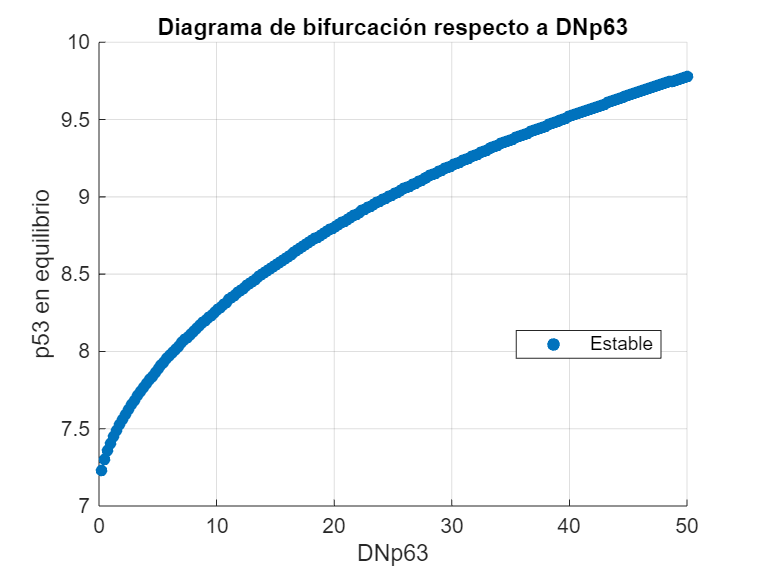


% Gráfico bifurcación
figure;
hold on;
tipos = unique(bifurcacion_tbl.Estabilidad);
colores = lines(length(tipos));

for i = 1:length(tipos)
    tipo_actual = tipos(i);
    idx = bifurcacion_tbl.Estabilidad == tipo_actual;
    scatter(bifurcacion_tbl.DNp63(idx), bifurcacion_tbl.p53(idx), 30, ...
        'filled', 'DisplayName', tipo_actual, 'MarkerFaceColor', colores(i,:));
end

xlabel('DNp63'); ylabel('p53 en equilibrio');
title('Diagrama de bifurcación respecto a DNp63');
legend('Location', 'best');
grid on;

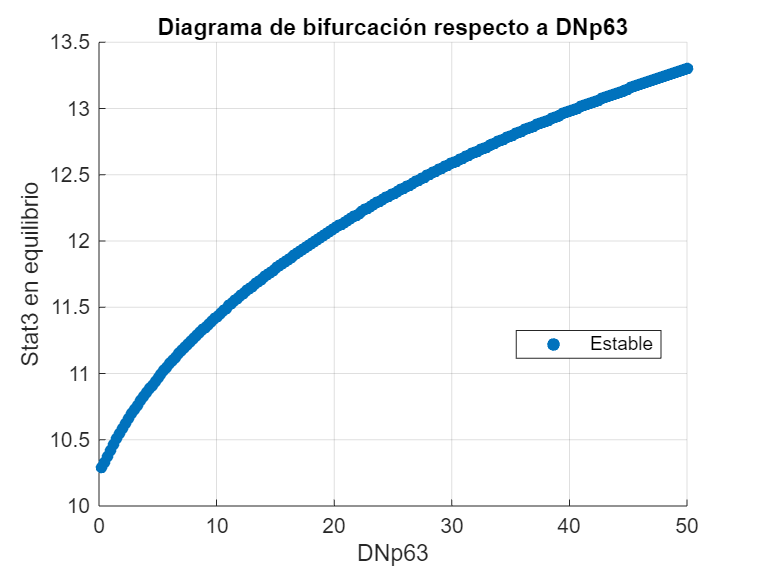



% Gráfico bifurcación
figure;
hold on;
tipos = unique(bifurcacion_tbl.Estabilidad);
colores = lines(length(tipos));

for i = 1:length(tipos)
    tipo_actual = tipos(i);
    idx = bifurcacion_tbl.Estabilidad == tipo_actual;
    scatter(bifurcacion_tbl.DNp63(idx), bifurcacion_tbl.Stat3(idx), 30, ...
        'filled', 'DisplayName', tipo_actual, 'MarkerFaceColor', colores(i,:));
end

xlabel('DNp63'); ylabel('Stat3 en equilibrio');
title('Diagrama de bifurcación respecto a DNp63');
legend('Location', 'best');
grid on;

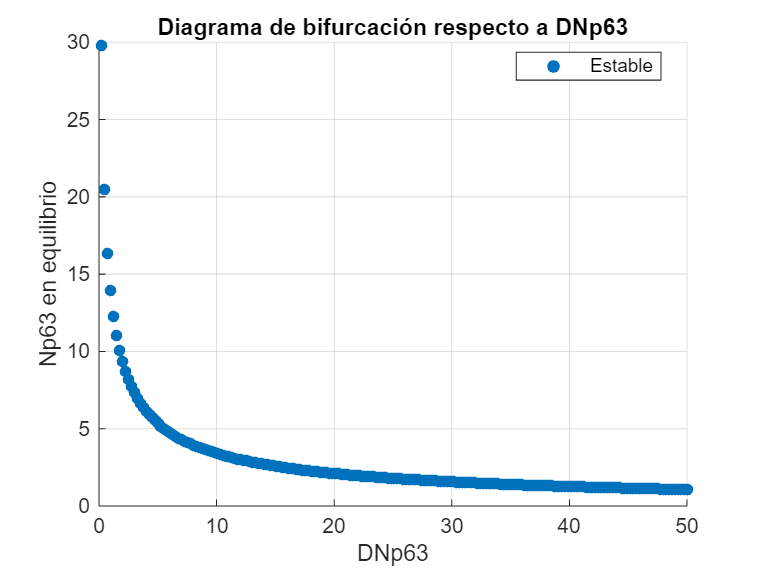


% Gráfico bifurcación
figure;
hold on;
tipos = unique(bifurcacion_tbl.Estabilidad);
colores = lines(length(tipos));

for i = 1:length(tipos)
    tipo_actual = tipos(i);
    idx = bifurcacion_tbl.Estabilidad == tipo_actual;
    scatter(bifurcacion_tbl.DNp63(idx), bifurcacion_tbl.Np63(idx), 30, ...
        'filled', 'DisplayName', tipo_actual, 'MarkerFaceColor', colores(i,:));
end

xlabel('DNp63'); ylabel('Np63 en equilibrio');
title('Diagrama de bifurcación respecto a DNp63');
legend('Location', 'best');
grid on;